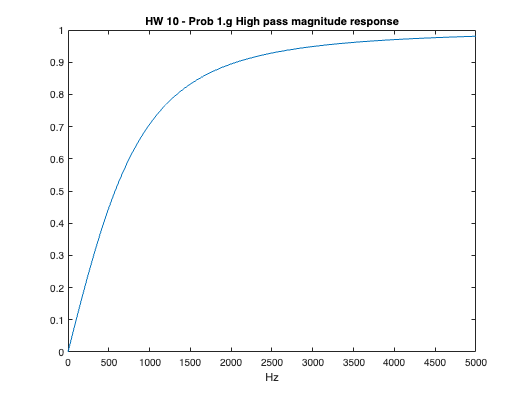

% HW10
% Prob 1.g
R = 1000;
C = 1/(2*pi)*10^-6;
cs = [1 0];
ds = [1 1/(R*C)];
f = (0:5000);
freqs(cs,ds);
figure;
h = freqs(cs,ds,2*pi*f);
plot(f,abs(h))
title('HW 10 - Prob 1.g High pass magnitude response');
xlabel('Hz')

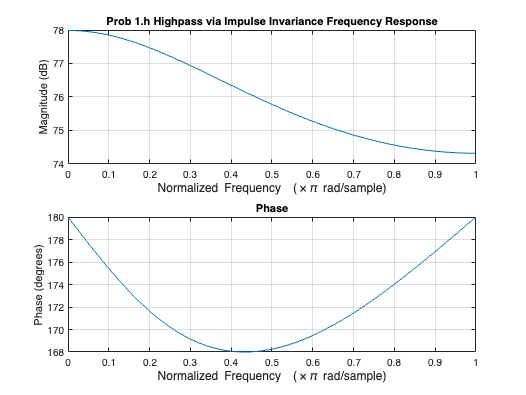


% Prob 1.h
% pi/2 maps to 1000 Hz, pi maps to 2000 Hz; Fs maps to 4000 Hz 
Fs = 4000;
Ts = 1/Fs;
[b,a] = imp_invr(cs,ds,Ts);
figure;
freqz(b,a);
title('Prob 1.h Highpass via Impulse Invariance Frequency Response')

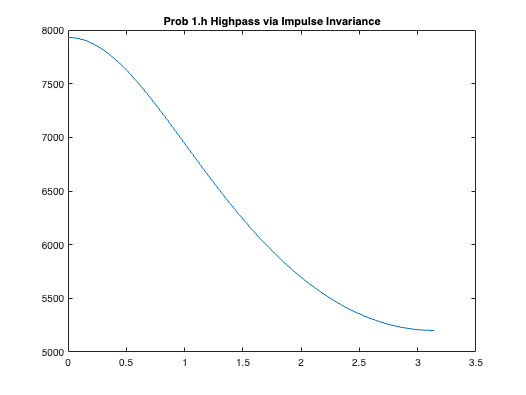

w = 0:pi/100:pi;
h = freqz(b,a,w);
plot(w,abs(h))
title('Prob 1.h Highpass via Impulse Invariance')

% We see that impulse invariance does not yield a proper
% highpass filter due to aliasing and thus
% should not be used for designing IIR highpass from
% continuous filters

% Prob 1.i
% cutoff is at pi/2 in discrete time frequency
% 1000 in continuous frequency
% Frequency warping is
% Omega = (2/T)*tan(w/2);
% T = (2/Omega)*tan(w/2)
Omega = 2*pi*1000;
Ts = (2/Omega)*tan(pi/4)

Ts = 3.1831e-04

Fs = 1/Ts

Fs = 3.1416e+03

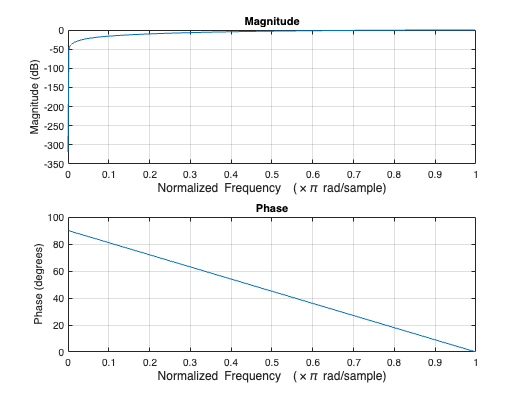

[b,a] = bilinear(cs,ds,Fs);
figure;
freqz(b,a);

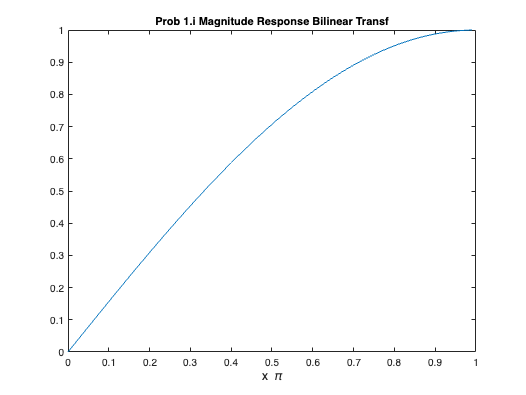

w = 0:0.01:0.99;
h = freqz(b,a,pi*w);
plot(w,abs(h))
title('Prob 1.i Magnitude Response Bilinear Transf')
xlabel('x \pi')

% We can see bilinear transformation is capable of
% mapping an analog high pass filter to a digital
% high pass filter

% Prob 2
% a
% design the analog butterworth filter
% Fs = 1000, Fs/2 = 500 Hz which maps to pi
% 20 Hz will map to 20/500*pi
% 60 Hz will map to 60/500*pi 
Wp = 2*pi*20

Wp = 125.6637

Ws = 2*pi*60

Ws = 376.9911

As = 20;
Rp = 2;
Fs = 1000;
Ts = 1/Fs;
[num, den] = afd_butt(Wp,Ws,Rp,As);


*** Butterworth Filter Order =  3 


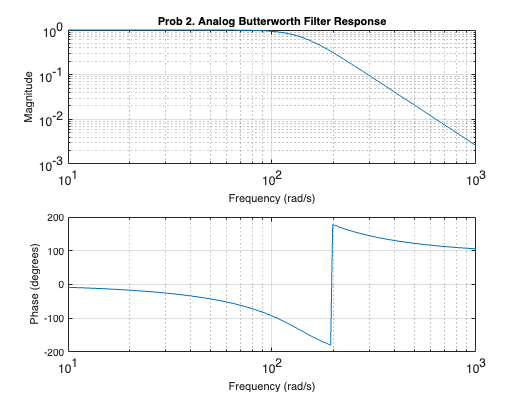

figure;
freqs(num,den)
title('Prob 2. Analog Butterworth Filter Response')

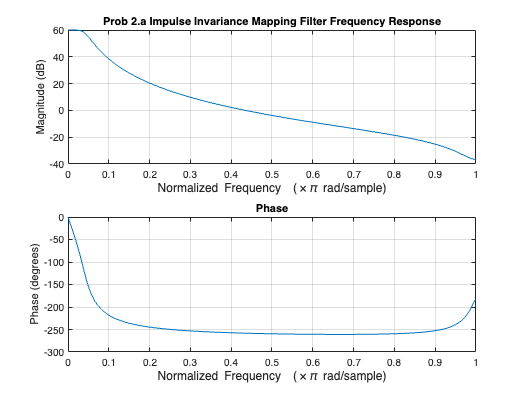


% Using impulse invariant
[b, a] = imp_invr(num,den,Ts);
binv = b;
ainv = a;
figure;
freqz(b,a);
title('Prob 2.a Impulse Invariance Mapping Filter Frequency Response')

figure;
wp = 20*pi/500

wp = 0.1257

ws = 60*pi/500

ws = 0.3770

w = pi*(0:1/500:1);
figure;
h = freqz(b,a,w);
absh = abs(h);
maxh = max(absh);
figure;
plot(w,absh)
title('Prob 2.a Impulse Invariance Mapping Filter Magnitude Response')
axis([0 ws 0 1000])
vp = interp1(w,absh,wp)

vp = 794.3299

vpdb = 20*log10(vp/maxh)

vpdb = -2.0000

vs = interp1(w,absh,ws)

vs = 48.3691

vsdb = 20*log10(vs/maxh)

vsdb = -26.3086

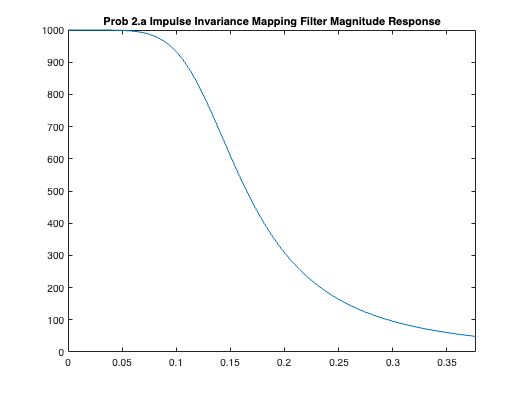

axis([0 ws 0 1000])

b

b =     0.0000
    1.1825
    1.0790


a

a =     1.0000
   -2.7256
    2.4876
   -0.7597



% The drop in passband is just acceptable (at 2 dB)
% and the drop in stopband exceeds the spec (at 26 dB)

% b
% we reuse the same analog butterworth filter obtained
% but use bilinear
% We check on frequency warping and map to midway
% between passband and stopband (20 + 60)/2 = 40
% 40*pi/(500*2)
Omega = 2*pi*40;
Ts = (2/Omega)*tan(40*pi/1000);
Fs = 1/Ts

Fs = 994.7307

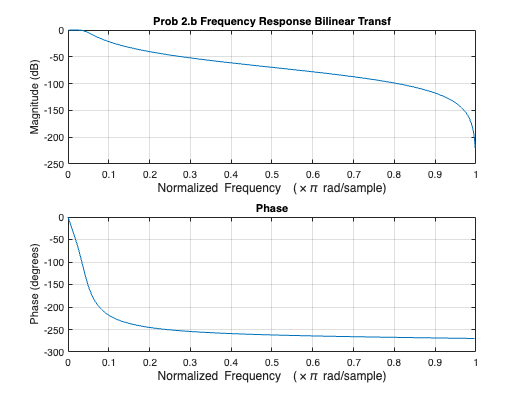

[b,a] = bilinear(num,den,Fs);
bbil = b;
abil = a;
figure;
freqz(b,a);
title('Prob 2.b Frequency Response Bilinear Transf')

wp = 20*pi/500

wp = 0.1257

ws = 60*pi/500

ws = 0.3770

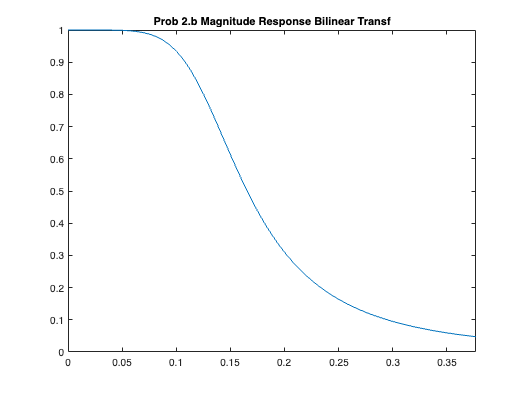

w = pi*(0:1/500:1);
figure;
h = freqz(b,a,w);
absh = abs(h);
maxh = max(absh);
figure;
plot(w,absh)
title('Prob 2.b Magnitude Response Bilinear Transf')
axis([0 ws 0 1])

vp = interp1(w,absh,wp)

vp = 0.7978

vpdb = 20*log10(vp/maxh)

vpdb = -1.9621

vs = interp1(w,absh,ws)

vs = 0.0474

vsdb = 20*log10(vs/maxh)

vsdb = -26.4813

% The drop in passband exceeds expectations (at 1.96 dB)
% and the drop in stopband exceeds the spec (at 26.5 dB)
b

b = 1.0e-03 *

    0.2870    0.8611    0.8611    0.2870


a

a =     1.0000   -2.7244    2.4854   -0.7588


% Prob 3.a
% Fs = 1000; Fs/2 = 500 = pi
Fs2 = 500;
% wplp and wslp below were relaxed to lead to design that would converge
% if we had set to be 54 and 66 the final filter would not have converged
% even as it is Matlab warned over precision issues
% wclp = 60*pi/Fs2
wplp = 50*pi/Fs2   % digital Passband freq in rad

wplp = 0.3142

wslp = 70*pi/Fs2   % digital Stopband freq in rad

wslp = 0.4398

Rp=3; % Passband ripple in dB
As=20; % Stopband attenuation in dB
Fs = 2*Fs2;
Ts = 1/Fs;

OmegaP = (2/Ts)*tan(wplp/2) % Prewarp Prototype Passband freq

OmegaP = 316.7689

OmegaS = (2/Ts)*tan(wslp/2) % Prewarp Prototype Stopband freq

OmegaS = 447.0530


% Butterworth Design
[num,den] = afd_butt(OmegaP,OmegaS, Rp,As)


*** Butterworth Filter Order =  7 


num = 3.2080e+17

den = 1.0e+17 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0455    3.2080


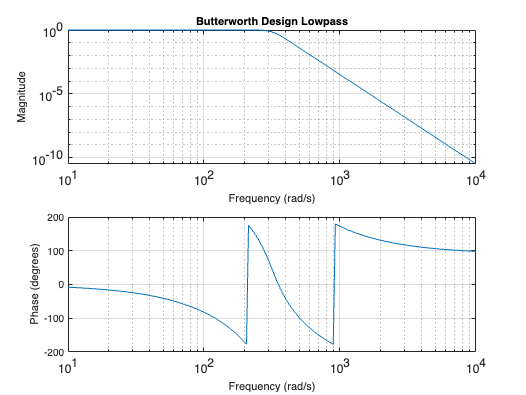

figure;
freqs(num,den)
title('Butterworth Design Lowpass')

[blp,alp] = bilinear(num,den,Fs);

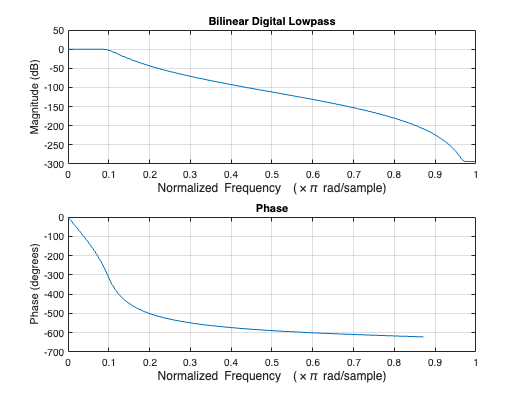

figure;
freqz(blp,alp)
title('Bilinear Digital Lowpass')

fu = 66/Fs2

fu = 0.1320

fl = 54/Fs2

fl = 0.1080

wu = fu*pi % design values to meet specs

wu = 0.4147

wl = fl*pi % design values to meet specs

wl = 0.3393

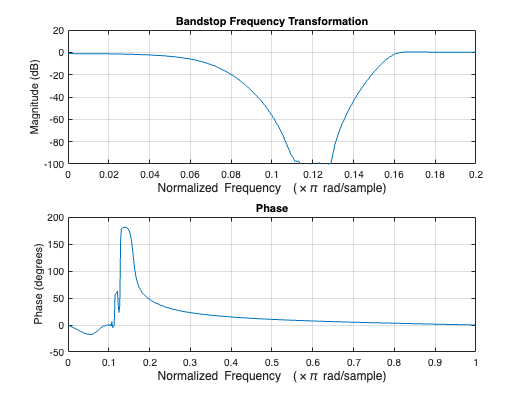


K = tan((wu - wl)/2)*tan(wplp/2);
alpha = cos((wu+wl)/2)/cos((wu-wl)/2);
a1 = 2*alpha/(K + 1);
a2 = (1-K)/(1+K);

Nz = [a2 -a1 1];
Dz = [1 -a1 a2];

[bbs,abbs] = zmapping(blp,alp,Nz,Dz);
figure;
freqz(bbs,abbs);
title('Bandstop Frequency Transformation')
axis([0 0.2 -100 20])

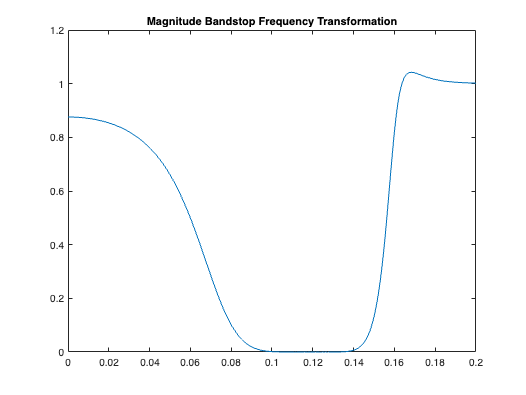

figure;
dw = pi/(100*Fs2);
w = 0:dw:pi;

% The specs state that attenuation must be
% greater than 20 dB between 58 and 62 Hz
lowi = find((w >= (58*pi/Fs2)) & (w <= (62*pi/Fs2)));

% The specs state that ripple must be
% less than 3 dB at less than 54 and > 66 Hz
highi = find((w <= (54*pi/Fs2)) | (w >= (66*pi/Fs2)));

h = freqz(bbs,abbs,w);
plot(w/pi,abs(h));
axis([0 0.2 0 1.2])
title('Magnitude Bandstop Frequency Transformation')

maxmag = 20*log10(max(abs(h(lowi)))) % should be less than -20 dB

maxmag = -99.7610

minmag = 20*log10(min(abs(h(highi)))) % should be greater than -3 dB

minmag = -85.8009


% Prob 3.b

load ekg.mat;
figure;
subplot(2,1,1);
plot(ekg60n);
title('Ekg60n signal')
subplot(2,1,2);
Ek = fftshift(fft(ekg60n))

Ek = 1.0e+02 *

   0.0253 + 0.0000i  -0.0032 - 0.0750i  -0.0008 - 0.0254i  -0.0541 - 0.1314i  -0.0389 - 0.0206i  -0.1302 - 0.0790i   0.0785 - 0.1070i  -0.0214 + 0.0729i  -0.0934 + 0.0527i  -0.0277 - 0.0928i   0.0719 + 0.1167i  -0.1492 - 0.0380i  -0.0041 - 0.0257i  -0.0540 + 0.0105i  -0.0996 - 0.1509i  -0.1208 - 0.1150i   0.1356 + 0.1362i  -0.0980 - 0.0244i  -0.0613 - 0.1182i  -0.0205 - 0.0754i   0.0127 + 0.1872i   0.0855 + 0.1089i  -0.0563 - 0.0284i  -0.0594 - 0.1597i   0.0391 + 0.0023i   0.0149 + 0.1255i   0.0428 + 0.1231i   0.2281 - 0.0710i  -0.0434 - 0.1194i   0.0751 - 0.1080i   0.0086 - 0.1194i  -0.0476 - 0.0531i   0.0422 + 0.0474i  -0.1486 - 0.0013i  -0.1081 - 0.0664i  -0.1078 + 0.0780i  -0.0181 + 0.1570i   0.0710 + 0.0842i   0.1116 - 0.2354i  -0.0031 + 0.0342i  -0.0683 - 0.1797i   0.1140 - 0.0038i  -0.0542 - 0.0299i   0.0098 + 0.0182i   0.0121 + 0.0761i   0.0374 - 0.1265i  -0.1343 - 0.0614i  -0.0422 - 0.0990i  -0.0758 - 0.0576i   0.1280 + 0.0580i


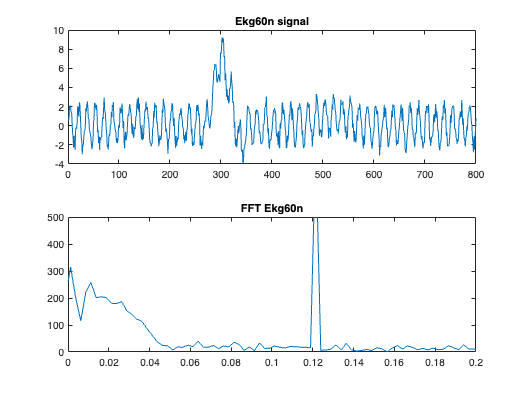

fss = -1:2/(length(Ek)-1):1;
plot(fss, abs(Ek));
title('FFT Ekg60n')
axis([0 0.2 0 500])

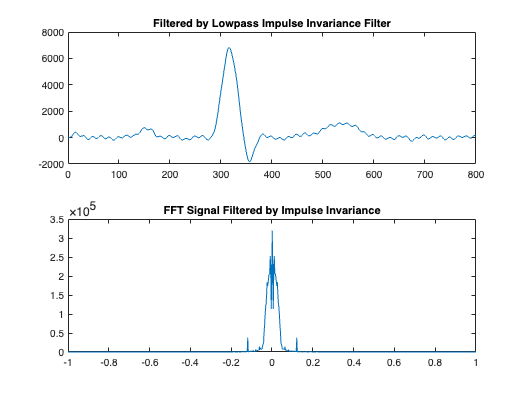

ekg_inv = filter(binv,ainv,ekg60n);
ekg_bil = filter(bbil,abil,ekg60n);
ekg_bs = filter(bbs,abbs,ekg60n);

figure;
subplot(2,1,1)
plot(ekg_inv);
title('Filtered by Lowpass Impulse Invariance Filter')
ekinv = fftshift(fft(ekg_inv));
subplot(2,1,2);
plot(fss,abs(ekinv));
title('FFT Signal Filtered by Impulse Invariance')

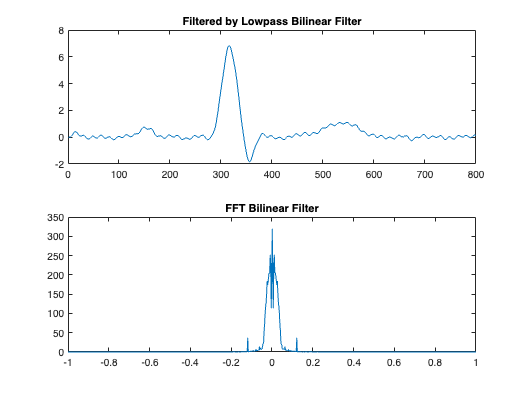


figure;
subplot(2,1,1)
plot(ekg_bil);
title('Filtered by Lowpass Bilinear Filter')
ekbil = fftshift(fft(ekg_bil));
subplot(2,1,2);
plot(fss,abs(ekbil));
title('FFT Bilinear Filter')

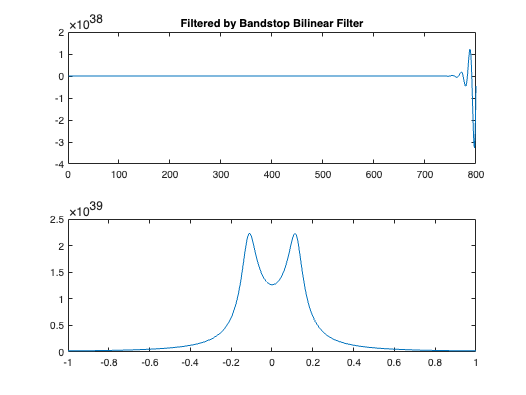


figure;
subplot(2,1,1)
plot(ekg_bs);
ekbs = fftshift(fft(ekg_bs));
title('Filtered by Bandstop Bilinear Filter')
subplot(2,1,2);
plot(fss,abs(ekbs));


% The impulse invariance methods were able to filter
% out some noise. The bandstop filter transformation
% did not result in correct filtered signal

% Prob 4
clear;
Fs = 200;
Fs2 = Fs/2;
Ts = 1/Fs;
t = 0:Ts:1;
nx = 5 + 5*cos(40*pi*t) + 5*cos(80*pi*t);
x = 5 + 5*cos(40*pi*t) + 5*cos(80*pi*t) + 5 * cos(190*pi*t);

num = [100*pi];
den = [1 100*pi];
% Prob 4.a Using 200 Hz
[binv, ainv] = imp_invr(num,den,Ts);
w = 0:pi/Fs:pi;
h = freqz(binv, ainv, w);
% normalize gain to be 1 at w = 0
% 4.a.i Filter coefficients
binv = binv/abs(h(1))

binv = 0.7921

ainv

ainv =     1.0000
   -0.2079


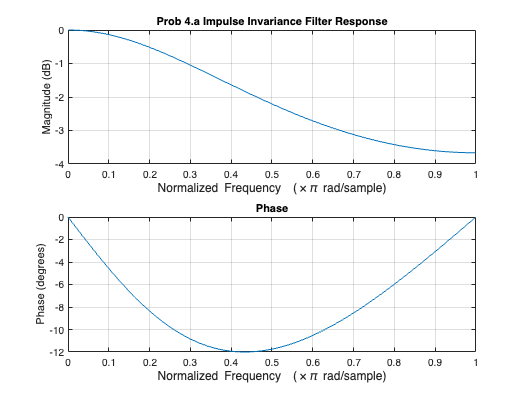

% 4.a.ii plot
figure;
freqz(binv,ainv);
title('Prob 4.a Impulse Invariance Filter Response')

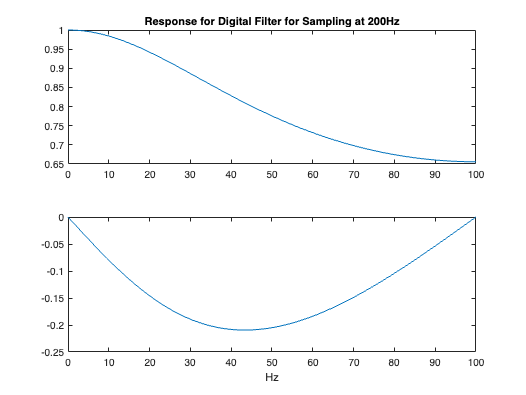


figure;
h = freqz(binv, ainv, w);
f200 = w/pi;
h200 = h;
subplot(2,1,1);
plot(w/pi*Fs2,abs(h));
title('Response for Digital Filter for Sampling at 200Hz');
subplot(2,1,2);
plot(w/pi*Fs2,angle(h));
xlabel('Hz')

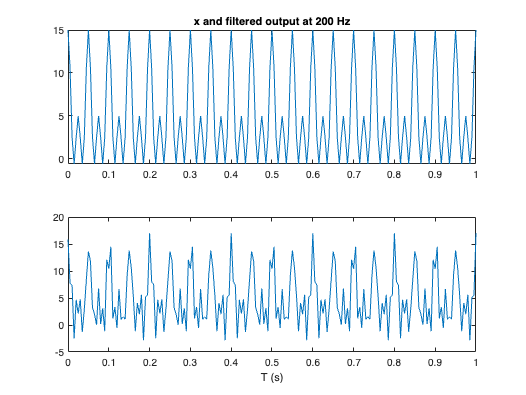

% 4.a.iii
y = filter(binv,ainv,x);
figure;
subplot(2,1,1);
plot(t,nx);
title('x and filtered output at 200 Hz')
subplot(2,1,2);
plot(t,y);
xlabel('T (s)')

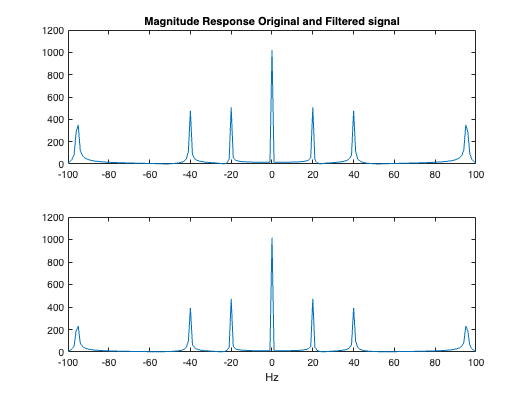


xk = fftshift(fft(x));
yk = fftshift(fft(y));
figure;
f = -Fs2:Fs/(length(xk) -1 ):Fs2;
subplot(2,1,1);
plot(f,abs(xk));
title('Magnitude Response Original and Filtered signal')
subplot(2,1,2);
plot(f,abs(yk));
xlabel('Hz');

% Prob 4.b

Fs = 1000;
Fs2 = Fs/2;
Ts = 1/Fs;
t = 0:Ts:1;
nx = 5 + 5*cos(40*pi*t) + 5*cos(80*pi*t);
x = 5 + 5*cos(40*pi*t) + 5*cos(80*pi*t) + 5 * cos(190*pi*t);

num = [100*pi];
den = [1 100*pi];
% Prob 4.b Using 1000 Hz
[binv, ainv] = imp_invr(num,den,Ts);
w = 0:pi/Fs:pi;
h = freqz(binv, ainv, w);


% normalize gain to be 1 at w = 0
% 4.b.i Filter coefficients
binv = binv/abs(h(1))

binv = 0.2696

ainv

ainv =     1.0000
   -0.7304


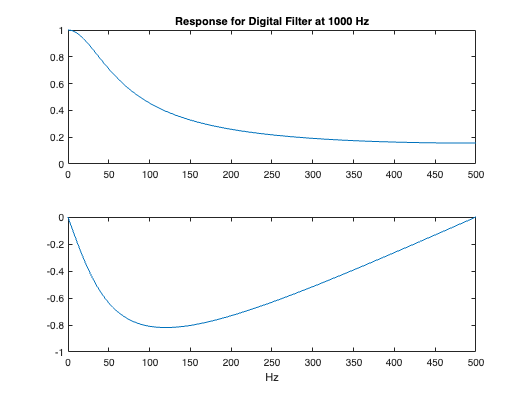

% 4.b.ii plot
freqz(binv,ainv);
figure;
h = freqz(binv, ainv, w);
f1000 = w/pi;
h1000 = h;
subplot(2,1,1);
plot(w/pi*Fs2,abs(h));
title('Response for Digital Filter at 1000 Hz');
subplot(2,1,2);
plot(w/pi*Fs2,angle(h));
xlabel('Hz')

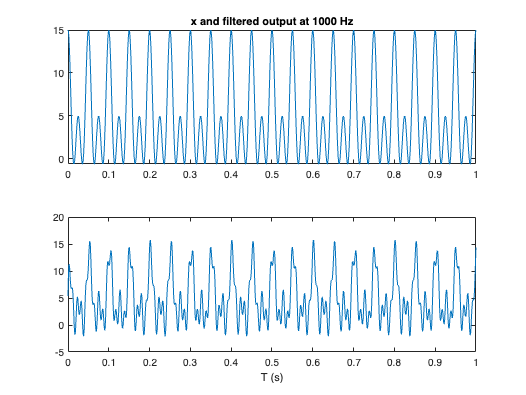

% 4.b.iii
y = filter(binv,ainv,x);
figure;
subplot(2,1,1);
plot(t,nx);
title('x and filtered output at 1000 Hz')
subplot(2,1,2);
plot(t,y);
xlabel('T (s)')

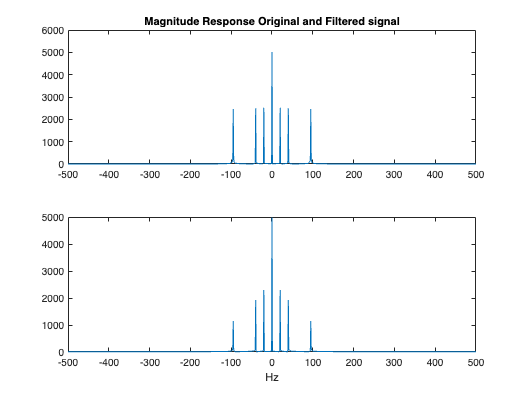


xk = fftshift(fft(x));
yk = fftshift(fft(y));
figure;
f = -Fs2:Fs/(length(xk) - 1 ):Fs2;

subplot(2,1,1);
plot(f,abs(xk));
title('Magnitude Response Original and Filtered signal')
subplot(2,1,2);
plot(f,abs(yk));
xlabel('Hz');

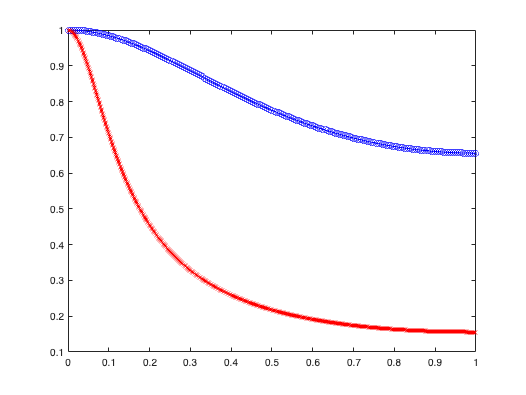


figure;
plot(f200,abs(h200),'bo-',f1000,abs(h1000),'rx-')

% The filter effect at a higher sampling rate obtained
% greater attenuation, and a more uniform response over
% the passband at lower sampling rate

% Prob 5
%
% We're given only digital filter spec, so we can
% design a Butterworth
clear;
wplp = 0.5*pi

wplp = 1.5708

wslp = 0.6*pi

wslp = 1.8850

Rp = 1;
As = 40;
Ts = 1;
Fs = 1/Ts;
WP = (2/Ts)*tan(wplp/2) % Prewarp Prototype Passband freq

WP = 2.0000

WS = (2/Ts)*tan(wslp/2) % Prewarp Prototype Stopband freq

WS = 2.7528


% Butterworth Design
[num,den] = afd_butt(WP,WS,Rp,As)


*** Butterworth Filter Order = 17 


num = 2.5759e+05

den = 1.0e+06 *

    0.0000    0.0000    0.0003    0.0019    0.0105    0.0459    0.1623    0.4765    1.1747    2.4448    4.2951    6.3356    7.7539    7.7135    6.0290    3.4931    1.3415    0.2576


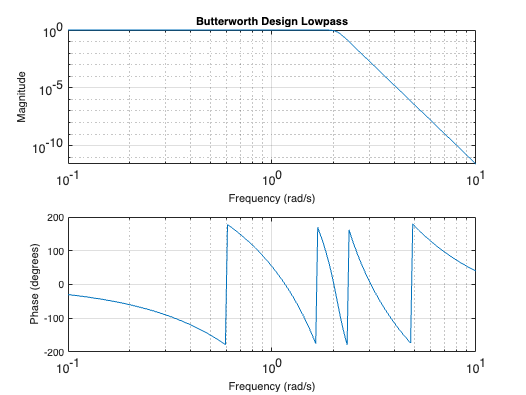

figure;
freqs(num,den)
title('Butterworth Design Lowpass')

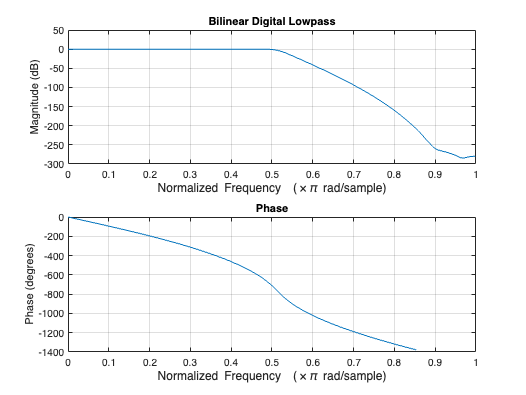

[blp,alp] = bilinear(num,den,Fs);
figure;
freqz(blp,alp)
title('Bilinear Digital Lowpass')

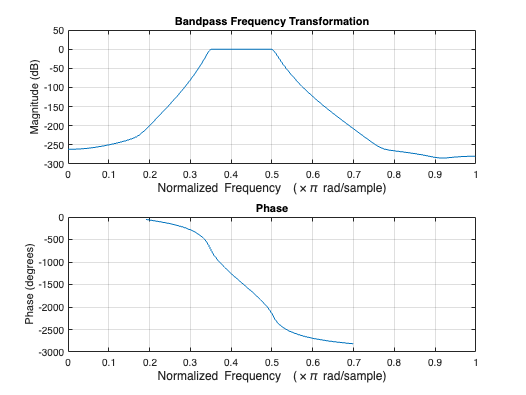


% We create the passband transformation
wu = 0.5*pi;
wl = 0.35*pi;

K = cot((wu-wl)/2)*tan(wplp/2);
alpha = cos((wu+wl)/2)/cos((wu-wl)/2);
a1 = 2*alpha*K/(K+1);
a2 = (K-1)/(K+1);

Nz = -[a2 -a1 1];
Dz = [1 -a1 a2];

[bbs,abbs] = zmapping(blp,alp,Nz,Dz);
figure;
freqz(bbs,abbs);
title('Bandpass Frequency Transformation')

filter_order = length(abbs)

filter_order = 35

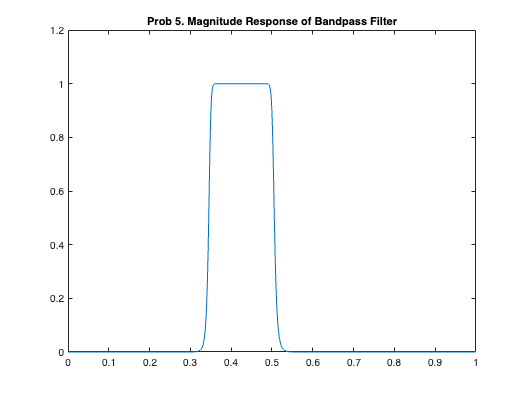

[h, w] = freqz(bbs,abbs);
figure
plot(w/pi,abs(h));
title('Prob 5. Magnitude Response of Bandpass Filter')

wpassband = find(abs(h)>=db2mag(-1));
wlindex = wpassband(1)

wlindex = 181

wupindex = wpassband(length(wpassband))

wupindex = 256

lower_edge_freq = w(wlindex-1)/pi

lower_edge_freq = 0.3496

upper_edge_freq = w(wupindex+1)/pi

upper_edge_freq = 0.5000

function [b,a] = imp_invr(c,d,T)
% Impulse Invariance Transformation from Analog to Digital Filter
% ---------------------------------------------------------------
% [b,a] = imp_invr(c,d,T)
%  b = Numerator polynomial in z^(-1) of the digital filter
%  a = Denominator polynomial in z^(-1) of the digital filter
%  c = Numerator polynomial in s of the analog filter
%  d = Denominator polynomial in s of the analog filter
%  T = Sampling (transformation) parameter
%
[R,p,k] = residue(c,d);  p = exp(p*T);
[b,a] = residuez(R,p,k);  b = real(b'); a = real(a');
end

function [b,a] = afd_butt(Wp,Ws,Rp,As)
% Analog Lowpass Filter Design: Butterworth
% -----------------------------------------
% [b,a] = afd_butt(Wp,Ws,Rp,As);
%  b = Numerator coefficients of Ha(s)
%  a = Denominator coefficients of Ha(s)
% Wp = Passband edge frequency in rad/sec; Wp > 0
% Ws = Stopband edge frequency in rad/sec; Ws > Wp > 0
% Rp = Passband ripple in +dB; (Rp > 0)
% As = Stopband attenuation in +dB; (As > 0)
%
if Wp <= 0
        error('Passband edge must be larger than 0')
end
if Ws <= Wp
        error('Stopband edge must be larger than Passband edge')
end
if (Rp <= 0) | (As < 0)
        error('PB ripple and/or SB attenuation ust be larger than 0')
end
N = ceil((log10((10^(Rp/10)-1)/(10^(As/10)-1)))/(2*log10(Wp/Ws)));
fprintf('\n*** Butterworth Filter Order = %2.0f \n',N)
OmegaC = Wp/((10^(Rp/10)-1)^(1/(2*N)));
[b,a]=u_buttap(N,OmegaC);
end

function [b,a] = u_buttap(N,Omegac)
% Unnormalized Butterworth Analog Lowpass Filter Prototype
% --------------------------------------------------------
% [b,a] = u_buttap(N,Omegac);
%      b = numerator polynomial coefficients of Ha(s)
%      a = denominator polynomial coefficients of Ha(s)
%      N = Order of the Butterworth Filter
% Omegac = Cutoff frequency in radians/sec
%
[z,p,k] = buttap(N);
      p = p*Omegac;
      k = k*Omegac^N;
      B = real(poly(z));
      b0 = k;  b = k*B;  a = real(poly(p));
end

function [bz,az] = zmapping(bZ,aZ,Nz,Dz)
% Frequency band Transformation from Z-domain to z-domain
% -------------------------------------------------------
% [bz,az] = zmapping(bZ,aZ,Nz,Dz)
% performs:
%           b(z)  b(Z)|
%          ---- = ----|     N(z)
%          a(z)   a(Z)|@Z = ----
%                           D(z)

bNzord = (length(bZ)-1)*(length(Nz)-1);
aDzord = (length(aZ)-1)*(length(Dz)-1);
bzord = length(bZ)-1; azord = length(aZ)-1;
bz = zeros(1,bNzord+1);
for k = 0:bzord
    pln = [1];
    for l = 0:k-1
        pln = conv(pln,Nz);
    end
    pld = [1];

    for l = 0:bzord-k-1
        pld = conv(pld,Dz);
    end
    bz = bz+bZ(k+1)*conv(pln,pld);
end
az = zeros(1,aDzord+1);
for k = 0:azord
    pln = [1];
    for l = 0:k-1
        pln = conv(pln,Nz);
    end
    pld = [1];
    for l = 0:azord-k-1
        pld = conv(pld,Dz);
    end
    az = az+aZ(k+1)*conv(pln,pld);
end
end